clear all;
clear;
close all;
f = [1 -1 1 1 1];
f_bar = [1 -1 -1 -1 1];
f_1 = [1 1 1 -1 1];
f_2 = [1 1 -1 1 1];
L = length(f);
t = 0:L-1;

[ac_f,lags] = xcorr(f);
[ac_bar,lags] = xcorr(f_bar);

zcp = ac_f + ac_bar;

[ac_f1,lags] = xcorr(f_1);
[ac_f2,lags] = xcorr(f_2);

zcp_bar = ac_f + ac_bar;

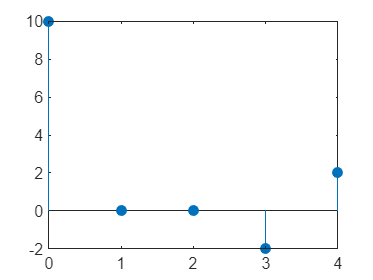

stem(lags,zcp,"filled");
xlim([0 4]);

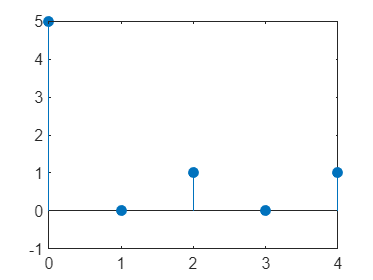

stem(lags,ac_f,"filled");
xlim([0 4]);

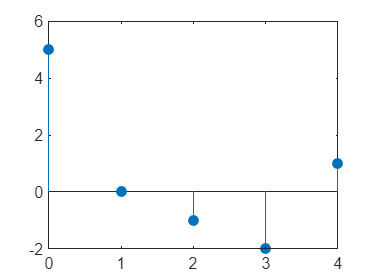

stem(lags,ac_bar,"filled");
xlim([0 4]);


stem(lags,zcp_bar,"filled");
xlim([0 4]);

stem(lags,ac_f1,"filled");
xlim([0 4]);

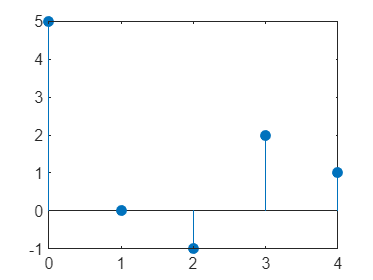

stem(lags,ac_f2,"filled");
xlim([0 4]);